clear variables
load('Tests/RPC_TT_test/e2_TL_RPC/coupled_tl_28par_10std.mat')
[~,d] = size(training_samples);


xi_train = training_samples(1:300,:);
y_train = vouts_train(1:300,:);
f_k = 1:100;
y_test = vouts;


m=1;
tic
[y_predict,n_rpc,d_rpc] = rpc_total(xi_train,y_train(:,f_k),samples,m,'Hermite',0.3,0.01,5e-3);
toc

Elapsed time is 1.176582 seconds.


norm(y_predict-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

ans = 0.0205

m=2;
tic
[y_predict,n_rpc,d_rpc] = rpc_total_Newton(xi_train,y_train(:,f_k),samples,m,'Hermite',0.3,0.01,5e-3);
toc

Elapsed time is 77.357548 seconds.


norm(y_predict-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

ans = 0.0073

m = 2;
[~,d] = size(xi_train);
N = (m+1)*ones(d,1);
x = TTrand(N,3);
x = TTorthogonalizeLR(x);
x = TTorthogonalizeRL(x);

tic
[y_predict2,N_coefficients,D_coefficients,n_iterations] =...
    rpc_TT(xi_train,y_train(:,f_k),x,samples,m,'Hermite',...
    0.1,0.01,3e-3,0.9,3);

    0.0022    0.0024   21.0000

    0.0019    0.0025    3.0000

    0.0019    0.0028    3.0000

    0.0020    0.0027    3.0000

    0.0020    0.0029    2.0000

    0.0019    0.0025    2.0000

    0.0017    0.0023    3.0000

    0.0018    0.0023    2.0000

    0.0017    0.0021    2.0000

    0.0014    0.0023    3.0000

    0.0015    0.0022    3.0000

    0.0019    0.0024    3.0000

    0.0015    0.0023    3.0000

    0.0027    0.0029    2.0000

    0.0020    0.0025    2.0000

    0.0030    0.0029    2.0000

    0.0020    0.0028    3.0000

    0.0020    0.0028    2.0000

    0.0015    0.0029    8.0000

    0.0015    0.0030    9.0000

    0.0015    0.0029    7.0000

    0.0017    0.0030    3.0000

    0.0020    0.0028    4.0000

    0.0013    0.0034   19.0000

    0.0014    0.0029    4.0000

    0.0017    0.0029    3.0000

    0.0015    0.0030    5.0000

    0.0014    0.0030    8.0000

    0.0013    0.0032   11.0000

    0.0013    0.0032   12.0000

    0.0015    0.0037   12.0000

    0.00

    0.0032    0.0349   73.0000



    0.0036    0.0490   85.0000

    0.0032    0.0259   59.0000

    0.0029    0.0313   45.0000



toc

Elapsed time is 72.686128 seconds.


err1 = norm(y_predict2(:,f_k)-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

err1 = 0.0100

fpoints = linspace(10,5e8,100);
m = 2;
r_max = 5;
freq_order = 80;

s2 = load('Tests/RPC_TT_test/e2_TL_RPC/coupled_tl_28par_fvariable.mat');
n_samples = length(s2.vouts_train3);
order = randperm(n_samples);
xi_train = s2.samples(order,:);
y_train = s2.vouts_train3(order);
tic
[y_predict2,N_coefficients,D_coefficients,n_iterations] = ...
    rpc_TT_freq2(xi_train,y_train,samples,fpoints,m,freq_order,'Hermite',...
    0.3,0.03,3e-3,0.9,r_max);

ans =     0.2618    0.2622


ans =     0.7918    0.7784


ans =     0.5824    0.5767


ans =     0.2473    0.2499


ans =     0.3595    0.3657


ans =     0.1707    0.1849


ans =     0.1363    0.1411


ans =     0.1263    0.1293


ans =     0.1163    0.1204


ans =     0.0671    0.0738


ans =     0.0815    0.0852


ans =     0.0571    0.0672


ans =     0.0511    0.0575


ans =     0.0685    0.0691


ans =     0.0505    0.0532


ans =     0.0470    0.0502


ans =     0.0524    0.0540


ans =     0.0387    0.0435


ans =     0.0331    0.0379


ans =     0.0309    0.0365


ans =     0.0285    0.0348


ans =     0.0263    0.0330


ans =     0.0255    0.0325


ans =     0.0242    0.0315


ans =     0.0239    0.0310


ans =     0.0232    0.0301


ans =     0.0226    0.0301


ans =     0.0215    0.0297


ans =     0.0211    0.0289


ans =     0.0204    0.0284


ans =     0.0201    0.0283


ans =     0.0235    0.0304


ans =     0.0198    0.0281


ans =     0.0226    0.0305


ans =     0.0194    0.0276


ans =     0.0202    0.0277


ans =     0.0203    0.0280


ans =     0.0201    0.0276


ans =     0.0185    0.0270


ans =     0.0192    0.0273


ans =     0.0178    0.0266


ans =     0.0182    0.0266


ans =     0.0187    0.0267


ans =     0.0192    0.0274


ans =     0.0173    0.0257


ans =     0.0184    0.0266


ans =     0.0168    0.0254


ans =     0.0172    0.0255


ans =     0.0170    0.0253


ans =     0.0196    0.0271


ans = 1×2
    0.0171    0.0252


ans = 1×2
    0.0175    0.0256


ans = 1×2
    0.0187    0.0265


ans = 1×2
    0.0180    0.0261


ans = 1×2
    0.0166    0.0250


ans = 1×2
    0.0165    0.0251


ans = 1×2
    0.0161    0.0247


ans = 1×2
    0.0160    0.0247


ans = 1×2
    0.0156    0.0248


ans = 1×2
    0.0152    0.0247


ans = 1×2
    0.0150    0.0244


ans = 1×2
    0.0147    0.0243


ans = 1×2
    0.0146    0.0243


ans = 1×2
    0.0143    0.0240


ans = 1×2
    0.0141    0.0239


ans = 1×2
    0.0140    0.0238


ans = 1×2
    0.0139    0.0238


ans = 1×2
    0.0137    0.0237


ans = 1×2
    0.0137    0.0235


ans = 1×2
    0.0136    0.0235


ans = 1×2
    0.0135    0.0234


ans = 1×2
    0.0134    0.0234


ans = 1×2
    0.0133    0.0234


ans = 1×2
    0.0132    0.0233


ans = 1×2
    0.0131    0.0232


ans = 1×2
    0.0130    0.0232


ans = 1×2
    0.0130    0.0232


ans = 1×2
    0.0129    0.0232


toc

Elapsed time is 220.241147 seconds.


err1 = norm(y_predict2(:,f_k)-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

err1 = 0.0508

% fpoints = linspace(10,3e6,100);
% m = 3;
% r_max = 7;
% freq_order = 80;
% [y_predict2,N_coefficients,D_coefficients,n_iterations] = ...
%     rpc_TT_freq(fpoints,xi_train,y_train(:,f_k),samples,m,freq_order,'Hermite',...
%     0.3,0.01,3e-3,0.9,r_max);
% 
% err1 = norm(y_predict2-vouts(:,f_k),'fro')/norm(vouts(:,f_k),'fro')

% m = 3;
% [~,d] = size(xi_train);
% fpoints2 = linspace(10,3e6,200);
% f_scale = 2/max(fpoints2);
% f_bias = -1;
% freq = reshape(f_scale*fpoints2+f_bias,length(fpoints2),1);
% test_samples = genPolynomialFreqSamplesTensor(samples,m,'Hermite',freq,freq_order);
% for i = 1:d
%     for j = 1:m
%         test_samples{i}(:,j+1) = test_samples{i}(:,j+1)*0.3^j;
%     end
% end
% b_predict = multi_r1_times_TT(test_samples,N_coefficients)./(1+multi_r1_times_TT(test_samples,D_coefficients));
% b_predict = reshape(b_predict,10000,[]);

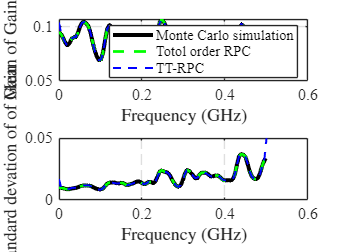

close all

y_mean0 = mean(abs(y_test));
y_sigma0 = std((y_test));

y_mean1 = mean(abs(y_predict));
y_sigma1 = std((y_predict));

y_mean2 = mean(abs(y_predict2));
y_sigma2 = std((y_predict2));

% y_mean3 = mean(abs(b_predict));
% y_sigma3 = std((b_predict));

fpoints = linspace(10,5e8,100);
scale = 1e9;
f = figure(1);
subplot(2,1,1);
hold on
plot(fpoints/scale,y_mean0,'k-','LineWidth',3);
plot(fpoints/scale,y_mean1,'g--','LineWidth',2);
plot(fpoints/scale,y_mean2,'b--','LineWidth',1.5);
% plot(fpoints2/scale,y_mean3,'r--','LineWidth',1.5);

legend('Monte Carlo simulation','Totol order RPC', 'TT-RPC')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of Gain','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

subplot(2,1,2);
hold on
plot(fpoints/scale,y_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,y_sigma1,'g--','LineWidth',2);
plot(fpoints/scale,y_sigma2,'b--','LineWidth',1.5);
% plot(fpoints2/scale,y_sigma3,'r--','LineWidth',1.5);


grid on
ylabel('Standard devation of of Gain','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

f.Position = [100 100 675 500];

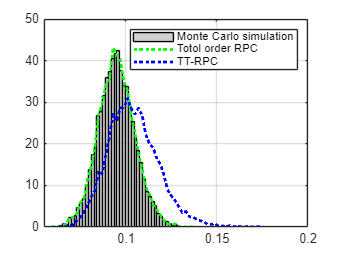



f_k = 1;

f = figure(2);
Hmc = histogram(abs(y_test(:,f_k)) ,50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N_k,edges] = histcounts(abs(y_predict(:,f_k)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_k,'g:','LineWidth',2)
[N_k,edges] = histcounts(abs(y_predict2(:,f_k)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N_k,'b:','LineWidth',2)
legend('Monte Carlo simulation','Totol order RPC', 'TT-RPC')